% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

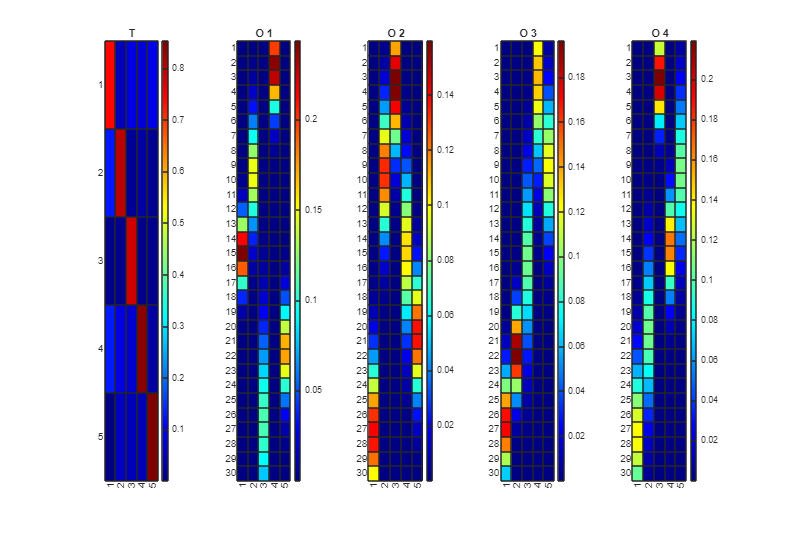

k = 5;
d = 30;
n = 4;

options.method = "random";
options.lambda = 10;

[T, O, pi] = generateHMM(k, d, n, options);


if(n < 5)
    figure('Renderer', 'painters', 'Position', [10 10 900 600])

    subplot(1, n+1, 1);
    h = heatmap(T, Colormap=jet());
    h.Title = 'T';
    
    for i = 1:n
        subplot(1, n+1, i+1);
        h = heatmap(O{i}, Colormap=jet());
        h.Title = ['O ' num2str(i)];
    end
end

Generate an observational sequence based on the defined HMM

T_seq = 1e6;
P3 = zeros(d, d, d, n);

use_optimal_JPT = true;

if use_optimal_JPT
    for i = 1:n
        U = {};
        U{1} = (O{i} * diag(pi) * T' / inv(diag(T * pi')));
        U{2} = O{i};
        U{3} = (O{i} * T);

        % i1 = 1 + d*(i-1);
        % i2 = d*i;

        P3(:, :, :, i) = cpdgen(U)/k;
    end
else
    [seq, states] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);
    for i = 1:n
        P3(:, :, :, i) = ProbabilityTensorGenerate(seq(i, :), 3, d);
    end
end

options.maxIter = 100;
options.tol = 1e-7;

max_iter = 500;

tic
U = cpd(P3, n * k);
toc

Elapsed time is 0.178853 seconds.


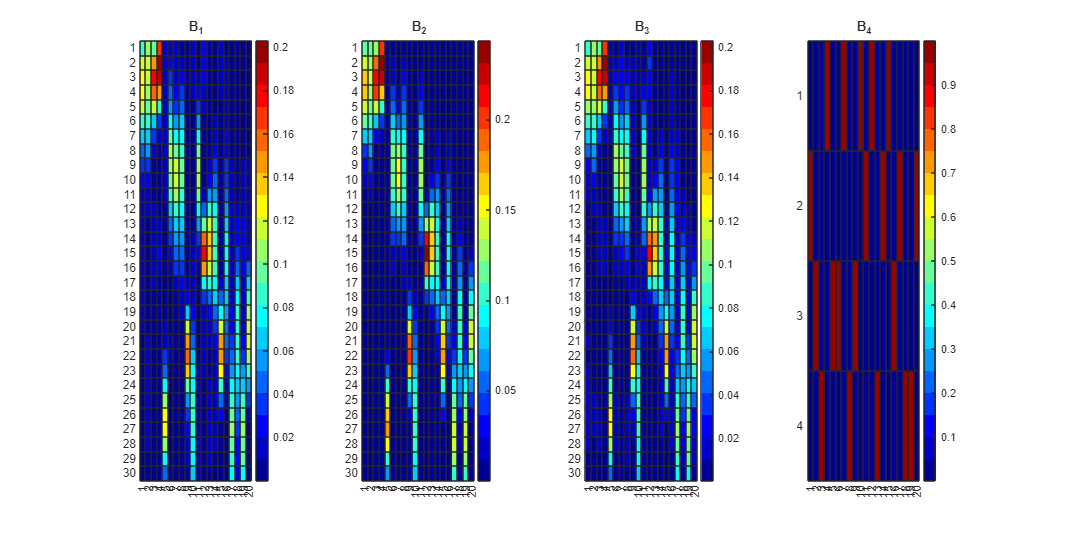


% tic
% [A, B, C] = coupled_cpd_with_perm_tracking(P3, k, max_iter);
% toc

A = Stochasticize(U{1});
B = Stochasticize(U{2});
C = Stochasticize(U{3});
D = Stochasticize(U{4});

% 
PlotFactorMatrices({A, B, C, D});

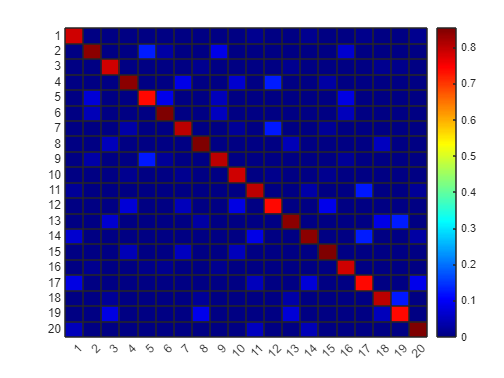

T_hat = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
figure()
heatmap(T_hat, Colormap=jet());


% [T_hat, row_perm, col_perm] = greedy_match(T_hat, T);
% 
% pi_hat = pi_hat(col_perm);
% 
% for i = 1:n
%     Oh = O_hat{i};
%     O_hat{i} = Oh(:, col_perm);
% end
% 
% 
% if(n < 5)
%     figure('Renderer', 'painters', 'Position', [10 10 900 600])
% 
%     subplot(3, n+1, 1);
%     h = heatmap(T, Colormap=jet());
%     h.Title = 'T';
% 
%     for i = 1:n
%         subplot(3, n+1, i+1);
%         h = heatmap(O{i}, Colormap=jet());
%         h.Title = ['O_' num2str(i)];
%     end
% 
% 
%     subplot(3, n+1, n+2);
%     h = heatmap(T_hat, Colormap=jet());
%     h.Title = 'T_{hat}';
% 
%     for i = 1:n
%         subplot(3, n+1, (n+1)+i+1);
%         h = heatmap(O_hat{i}, Colormap=jet());
%         h.Title = ['O_{hat} ' num2str(i)];
%     end
% 
% 
%     subplot(3, n+1, 2*n+3);
%     h = heatmap(abs(T - T_hat), Colormap=jet());
%     h.Title = 'T_{Error}';
% 
%     for i = 1:n
%         subplot(3, n+1, 2*(n+1)+i+1);
%         h = heatmap(abs(O{i} - O_hat{i}), Colormap=jet());
%         h.Title = ['O_{Error} ' num2str(i)];
%     end
% end
% 
% 
% 
% figure()
% semilogy(output.relerr)
% grid on;
